# **Week 5 : Examining BER vs Transmitted Power**

The code below examines the variation of the bit error rate (BER) with the variation of the transmitted laser power in the presence of varying noise at the receiver

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using BPSK and QPSK.

- An IQ modulator which modulates the output of a laser according to an electrical signal.

### Modulation

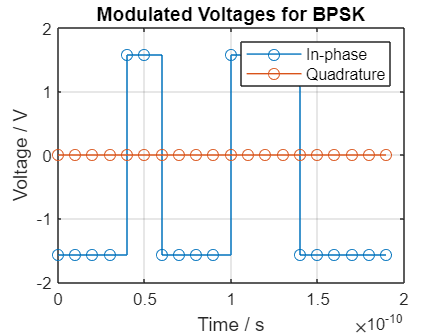

clear all; clearvars;

% Parameters
NSymb = 500000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
maxPw= 30; % Maximum laser power in dB
laserPwArr= [-10:maxPw]; % Sampled laser power values in dB
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevels = [-pi/2, pi/2]'; % Discrete voltage levels for BPSK and QPSK
DCOffset = 0; % DC offset of modulated current in V

% -------------------------------------------------------------------------------

% FOR BPSK:
% Generating random bit sequence(s)
sourceBitsBPSK = randi([0 1], NSymb, length(laserPwArr)); % Matrix of source bits for BPSK
sourceSymbolsBPSK = pskmod(sourceBitsBPSK, 2); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_BPSK = ones(size(sourceSymbolsBPSK)); vQ_BPSK = zeros(size(sourceSymbolsBPSK));

vI_BPSK(real(sourceSymbolsBPSK)>0) = voltageLevels(2); % Maps 1 -> pi/2
vI_BPSK(real(sourceSymbolsBPSK)<0) = voltageLevels(1); % Maps -1 -pi/2

vI_BPSK_upsampled = repelem(vI_BPSK, SpS, 1); % Upsampling according to SpS
vQ_BPSK_upsampled = repelem(vQ_BPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase voltage
stairs(t(1:10*SpS), vI_BPSK_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_BPSK_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltages for BPSK")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

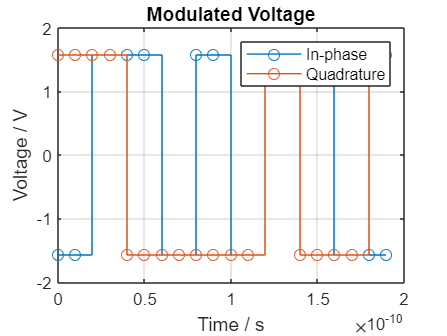


% -------------------------------------------------------------------------------

% FOR QPSK:
% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, length(laserPwArr)); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_QPSK = ones(size(sourceSymbolsQPSK)); vQ_QPSK = zeros(size(sourceSymbolsQPSK));

vI_QPSK(real(sourceSymbolsQPSK)>0) = voltageLevels(2); % Maps 1 -> pi/2
vI_QPSK(real(sourceSymbolsQPSK)<0) = voltageLevels(1); % Maps -1 -pi/2
vQ_QPSK(imag(sourceSymbolsQPSK)>0) = voltageLevels(2); % Maps 1 -> pi/2
vQ_QPSK(imag(sourceSymbolsQPSK)<0) = voltageLevels(1); % Maps -1 -pi/2

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

### IQ Modulation

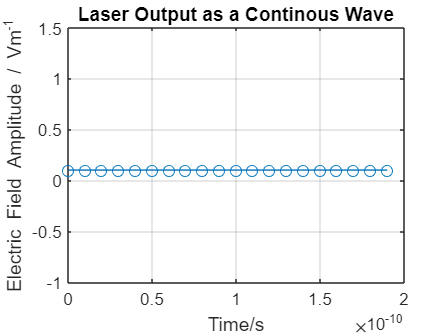

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 10;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a contniuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals

% Visualising output from laser
plot(t(1:20), real(laserE(1:20)), "o-");
title("Laser Output as a Continous Wave");
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}");
grid on

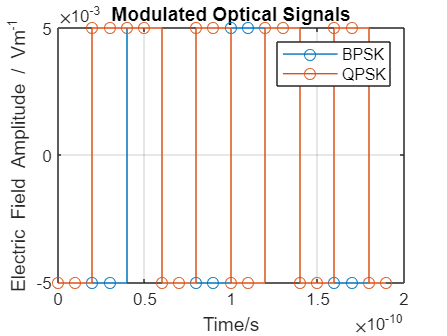


% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

for i=1:length(laserPwArr)
    laserE = Laser(laserPwArr(i), lineWidth, SpS, Rs, NSymb, 1); 
    modOpticSigBPSK(:,i) = IQModulatorModified(vI_BPSK_upsampled(:,i), vQ_BPSK_upsampled(:,i), laserE, Vpi);
    modOpticSigQPSK(:,i) = IQModulatorModified(vI_QPSK_upsampled(:,i), vQ_QPSK_upsampled(:,i), laserE, Vpi);
end

% Visualising modulated optical signals
stairs(t(1:10*SpS), real(modOpticSigBPSK(1:10*SpS,1)), "o-");
hold on
stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1)), "o-");
title("Modulated Optical Signals")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("BPSK", "QPSK")
grid on
hold off

## Optical Channel

### Attenuation

## Receiver

### Optical Front-End

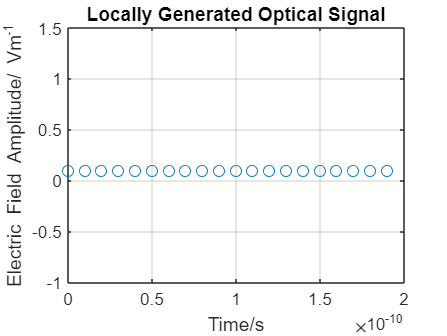

% Generating Local optical signal for coherent detection
Elo = Laser(10, lineWidth, SpS, Rs, NSymb, 1); % Identical to initial laser source

% Visualising locally generated optical signal
plot(t(1:20), real(Elo(1:20,1)), "o");
title("Locally Generated Optical Signal");
xlabel("Time/s")
ylabel("Electric Field Amplitude/ Vm^{-1}")
grid on

% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

count = 1;

for i=1:size(modOpticSigBPSK,2)  % Output from Optical Front-End
    OpticFEOutBPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigBPSK(:,i), Elo, eta_ph, 1);
    OpticFEOutQPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigQPSK(:,i), Elo, eta_ph, 1);

    count = count+2;
end

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components
% BPSK
OpticFEOutBPSK_I = TIA_Gain*OpticFEOutBPSK(:, 1:2:end); OpticFEOutBPSK_Q = TIA_Gain*OpticFEOutBPSK(:, 2:2:end); 

% QPSK
OpticFEOutQPSK_I = TIA_Gain*OpticFEOutQPSK(:, 1:2:end); OpticFEOutQPSK_Q = TIA_Gain*OpticFEOutQPSK(:, 2:2:end);

### Adding AWGN at the Receiver

% Adding AWGN at the receiver
% Power per bit associated with the laser output with the most power is calculated
powerPerSymb_BPSK = abs(OpticFEOutBPSK_I(1,end)+1i*OpticFEOutBPSK_Q(1,end)).^2;  
powerPerSymb_QPSK = abs(OpticFEOutQPSK_I(1,end)+1i*OpticFEOutQPSK_Q(1,end)).^2; 

% Calculating the std. deviation of the noise based on the required overall SNR
SNR_dB = 10; SNR_Lin = 10^(SNR_dB/10);
AWGN_StdDev_BPSK = sqrt(powerPerSymb_BPSK/SNR_Lin); AWGN_StdDev_QPSK = sqrt(powerPerSymb_QPSK/SNR_Lin);

% BPSK
v_AWGN_BPSK = (OpticFEOutBPSK_I+1i*OpticFEOutBPSK_Q) + (1/sqrt(2))*AWGN_StdDev_BPSK*(randn(size(OpticFEOutBPSK_I)) + 1i*randn(size(OpticFEOutBPSK_I)));

% QPSK
v_AWGN_QPSK = (OpticFEOutQPSK_I+1i*OpticFEOutQPSK_Q) + (1/sqrt(2))*AWGN_StdDev_QPSK*(randn(size(OpticFEOutQPSK_I)) + 1i*randn(size(OpticFEOutQPSK_I)));

## DSP

### Downsampling

% Cancelling the scaling factor and downsampling:
% BPSK
voltageI_BPSK = real(v_AWGN_BPSK(1:SpS:end, :)); voltageQ_BPSK = imag(v_AWGN_BPSK(1:SpS:end, :));
% QPSK
voltageI_QPSK = real(v_AWGN_QPSK(1:SpS:end, :)); voltageQ_QPSK = imag(v_AWGN_QPSK(1:SpS:end, :));


### Decoding and Decision

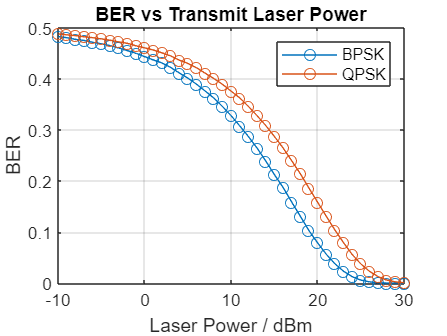

% Decoding recieved symbols

% BPSK
decodedSymbolsBPSK = ones(size(voltageI_BPSK)); 
decodedSymbolsBPSK(voltageI_BPSK > 0) = 1; decodedSymbolsBPSK(voltageI_BPSK <= 0) = -1;
decodedIntsBPSK = pskdemod(decodedSymbolsBPSK, 2);
decodedBitsBPSK = int2bit(decodedIntsBPSK, 1);

% --------------------------------------------------------------------------------------------

% QPSK
decodedSymbolsQPSK = voltageI_QPSK + 1i*voltageQ_QPSK;
decodedIntsQPSK = pskdemod(decodedSymbolsQPSK, 4, pi/4);
decodedBitsQPSK = int2bit(decodedIntsQPSK, 2);


for i=1:length(laserPwArr)
    [~, BER_BPSK(i,1)] = biterr(decodedBitsBPSK(:,i), sourceBitsBPSK(:,i));
    [~, BER_QPSK(i,1)] = biterr(decodedBitsQPSK(:,i), sourceBitsQPSK(:,i));
end

% Visualising variation of BER with link length

plot(laserPwArr, BER_BPSK, "-o");
hold on
plot(laserPwArr, BER_QPSK, "-o");
title("BER vs Transmit Laser Power")
xlabel("Laser Power / dBm")
ylabel("BER")
legend("BPSK", "QPSK")
grid on
hold off